# Lab S12

syms t y
f = matlabFunction(t^2 - 3*y); % función de la EDO
a = 2; b = 3; n = 10; y0 = -2;

euler = Euler(f, a, b, y0, n)

euler =    -1.0000   -2.0000    7.0000    0.3333
   -0.6667    0.3333   -0.5556    0.1481
   -0.3333    0.1481   -0.3333    0.0370
         0    0.0370   -0.1111         0
    0.3333         0    0.1111    0.0370
    0.6667    0.0370    0.3333    0.1481
    1.0000    0.1481    0.5556    0.3333
    1.3333    0.3333    0.7778    0.5926
    1.6667    0.5926    1.0000    0.9259
    2.0000    0.9259    1.2222    1.3333


rugenKutta = RK2(f, a, b, y0, n)

rugenKutta =    -1.0000   -2.0000    7.0000   -0.5556   -0.9259
   -0.6667   -0.9259    3.2222   -0.3333   -0.4444
   -0.3333   -0.4444    1.4444   -0.1111   -0.2222
         0   -0.2222    0.6667    0.1111   -0.0926
    0.3333   -0.0926    0.3889    0.3333    0.0278
    0.6667    0.0278    0.3611    0.5556    0.1806
    1.0000    0.1806    0.4583    0.7778    0.3866
    1.3333    0.3866    0.6181    1.0000    0.6562
    1.6667    0.6562    0.8090    1.2222    0.9948
    2.0000    0.9948    1.0156    1.4444    1.4048


syms y(t) t;
exac = dsolve(diff(y,t) == f(t,y), y(a) == y0)

$$exac = \frac{t^{2}}{3}-\frac{2\,t}{9}-\frac{71\,{\mathrm{e}}^{-3\,t}\,{\mathrm{e}}^{-3}}{27}+\frac{2}{27}$$

solexac = matlabFunction(exac)

solexac = function_handle with value:
    @(t)t.*(-2.0./9.0)+t.^2./3.0-exp(t.*-3.0).*exp(-3.0).*(7.1e+1./2.7e+1)+2.0./2.7e+1


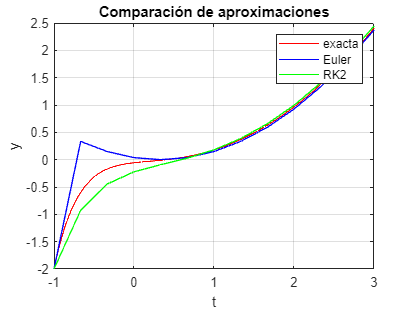


z = Euler(f, a, b, y0, n);
solEuler = z(:, 1:2);

z = RK2(f, a, b, y0, n);
solRK2 = z (:, 1:2);

tt = a:0.001:b;

exacta = solexac(tt);
plot(tt, exacta, "r", solEuler(:, 1), solEuler(:, 2), "b", solRK2(:, 1), solRK2(:, 2), "g")
legend('exacta', 'Euler', 'RK2');

% Personalizar el título y los ejes
title('Comparación de aproximaciones');
xlabel('t');
ylabel('y');

% Mostrar la cuadrícula
grid on;

syms x y;
f = matlabFunction(-6.8*x*y)

f = function_handle with value:
    @(x,y)x.*y.*(-3.4e+1./5.0)


a = 0; b = 1; h = 0.5; y0 = 4;

z = RK2(f,a,b,y0,2)

z =          0    4.0000         0  -13.6000    0.6000
    0.5000    0.6000   -2.0400    2.8560    0.8040
    1.0000    0.8040   -5.4672   19.6819    4.3577



a = z(1,3)

a = 0

b = z(1,4)

b = -13.6000

c = z(2,3)

c = -2.0400

d = z(2,4)

d = 2.8560

e = z(2,5)

e = 0.8040


rpta = a + b + c + d + e

rpta = -11.9800

Método de euler

function z = Euler(f, a, b, y0, n)
    % f = función
    % a = primer valor
    % b = último valor
    % y0 = valor inicial
    % n = intervalos

    h = (b-a)/n; % Tamaño de paso
    t = [a:h:b]'; % Valor de cada punto
    z = [];

    for i = 1:(n+1)
        k1 = f(t(i), y0);
        y1 = y0 + k1*h;
        z = [z; t(i) y0 k1 y1];
        y0 = y1;
    end
end

Runge Kutta orden 2

function z = RK2(f, a, b, y0, n)
    % f = función
    % a = primer valor
    % b = último valor
    % y0 = valor inicial
    % n = intervalos

    h = (b-a)/n; % Tamaño de paso
    t = [a:h:b]'; % Valor de cada punto
    z = [];

    for i = 1:(n+1)
        k1 = f(t(i), y0);
        k2 = f(t(i) + h, y0 + k1*h);
        y1 = y0 + (k1/2 + k2/2)*h;
        z = [z; t(i) y0 k1 k2 y1];
        y0 = y1;
    end
end

Runge Kutta orden 4